close all; clear all; clc

% simulation parameters
g = 9.81; L = 4;
tspan = 0:0.1:15;

% initial state
% [theta, theta_dot]
y0 = [deg2rad(20) 0];

% simulate the pendulum
[t,y] = ode45(@(t,y)simpend(y,g,L),tspan,y0);

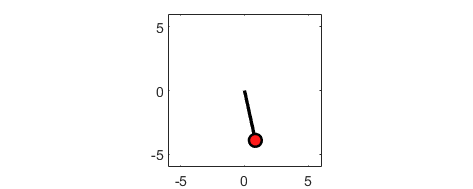

% create a fun animation
for k=1:length(t)
    drawpend(y(k,:),L);
end

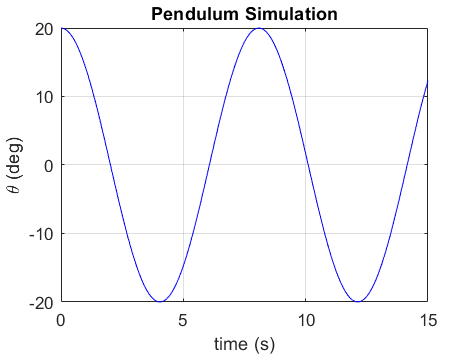

% plot the pendulum's motion
figure
plot(t,rad2deg(y(:,1)),'b-')
title('Pendulum Simulation')
xlabel('time (s)')
ylabel('\theta (deg)')
grid on